# Segmentation Algorithm v2.0

clear all;
close all;
clc;
pause on;

## Setting Variables 

main_path = 'D:\UDENAR\Electronic Engineering\Trabajo de Grado';
dataset = 'Training A Normal';
dataset_path = fullfile(main_path, 'Databases\Heart Sounds', dataset);
annot_path = fullfile(main_path, 'Databases\Heart Sounds\', strcat(dataset, '.csv'));
annotations = readtable(annot_path, 'ReadRowNames', true, 'Delimiter', ',', 'NumHeaderLines', 1);
version = 'v2.0';
env_method = 'Teager';
results_path = fullfile(main_path, 'Results', env_method, version);
metrics_path = fullfile(results_path, 'Segmentation metrics');
seg_hs_path = fullfile(results_path, 'Segmented heart sounds');
mse_filename = 'A_training_mse.xlsx';
annot_filename = 'A_training_annotations.xlsx';
metrics_filename = 'A_training_metrics.xlsx';

global plots;
plots = "on";

file_type = 'audio';
save_hs = true;

error_list = [];
metrics_list = [];

## Reading Heart Sounds

audios = get_signals(dataset_path);

## Applying segmentation algorithm to heart sounds

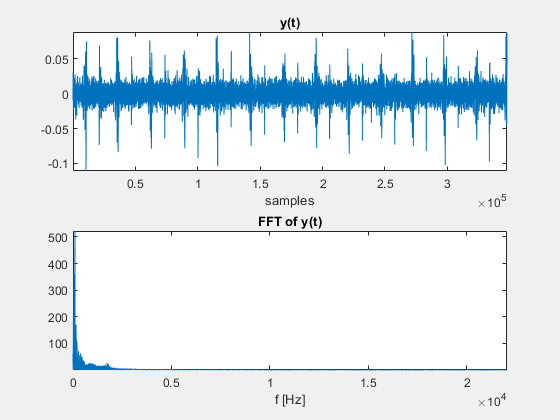

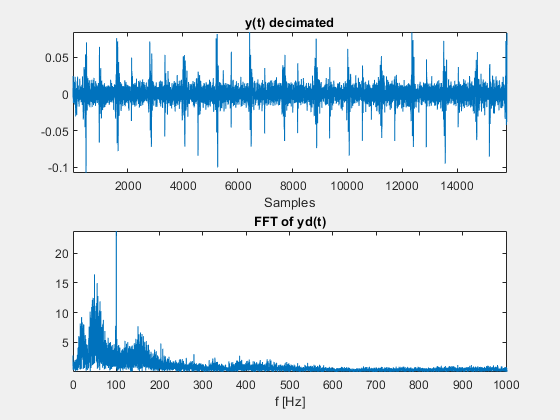

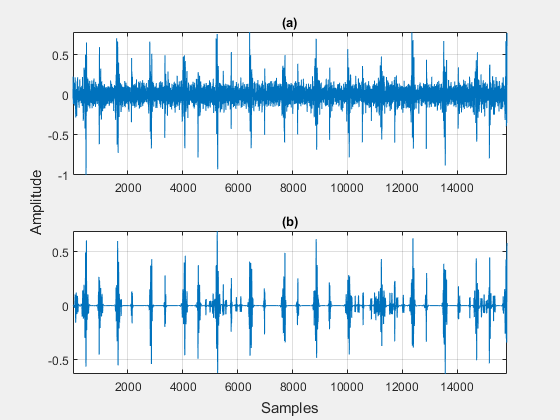

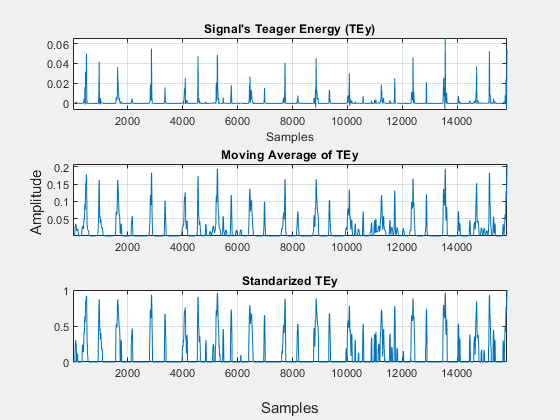

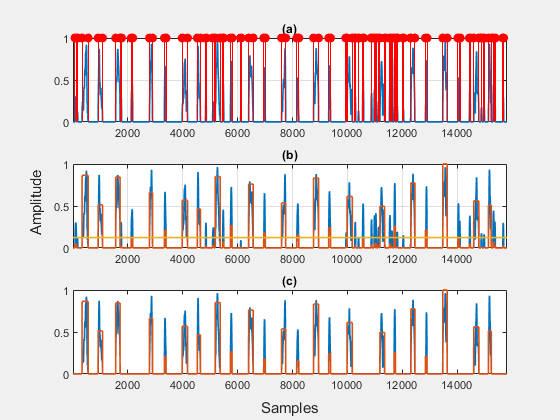

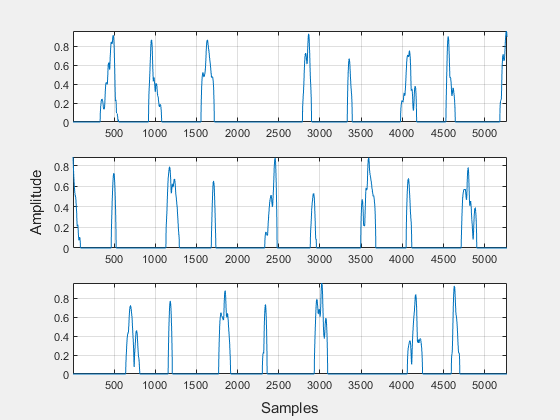

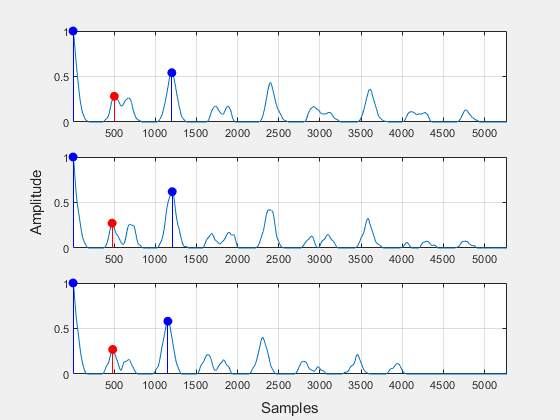

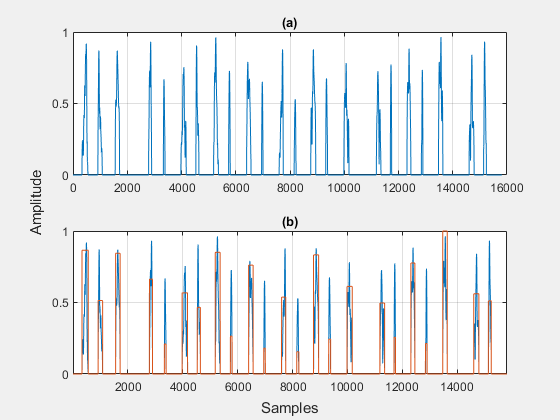

201102081321.wav method 1


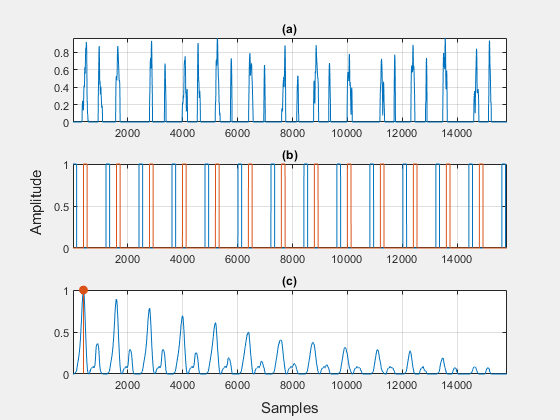

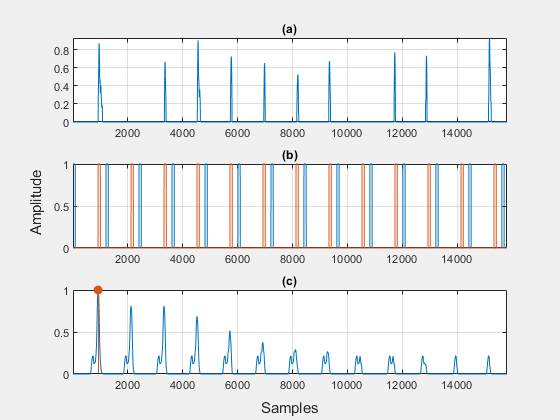

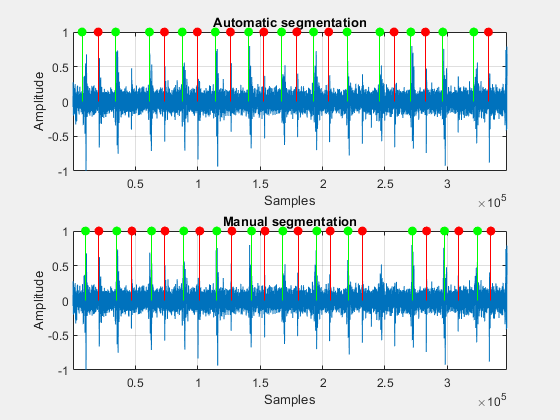

for i=4
    try
        %Get PCG signal, sampling frequency, name, and number of samples
        audio_idx = i;
        y = audios{audio_idx, 1};
        fs = audios{audio_idx, 2};
        audio_filename = audios{audio_idx, 3};
        label = int2str(-1);
        N = length(y);
        %Fast Fourier Transform of the signal
        f = (0:N/2)*fs/N;
        Y = abs(fft(y)); Y = Y(1:floor(N/2)+1);
        figure('Visible', plots);
        subplot(211); plot(y); title('y(t)'); xlabel('samples'); axis tight;
        subplot(212); plot(f, Y); title('FFT of y(t)'); xlabel('f [Hz]'); axis tight;

##             Decimation

        D = floor(fs/2000);
        fs1 = fs/D;
        yd = decimate(y, D, 'fir');
        Nd = length(yd);
        %Decimated signal's Fast Fourier Transform
        f1 = (0:Nd/2)*fs1/Nd;
        Yd = abs(fft(yd)); Yd = Yd(1:floor(Nd/2)+1);
        figure("Visible", plots);
        subplot(211); plot(yd); title('y(t) decimated'); xlabel('Samples'); axis tight;
        subplot(212); plot(f1, Yd); title('FFT of yd(t)'); xlabel('f [Hz]'); axis tight;

##             Normalization

        y1 = yd/max(abs(yd));
        Y1 = Yd/max(abs(Yd));

##             Adaptative Filter

        y2 = adaptative_filter(y1, 'coif5');
        y2 = y2(1:Nd)/max(abs(y2));
        Y2 = abs(fft(y2)); Y2 = Y2(1:floor(Nd/2)+1);

##             Signal Envelope

        TEy_n = get_envelope(y2, 'Teager', 20);

##             Energy and Thresholding

        [onsets, offsets, TEy_n] = get_on_off_sets(TEy_n);
        [TE_energy, th_TE_energy, TE_th, energy_th] = energy_threshold(TEy_n, onsets, offsets, 1);

##             Windows

        n_windows = floor((Nd/fs1)/2);
        n_windows(n_windows==0) = 1;
        n_samples = floor(Nd/n_windows);
        TEw = get_windows(TE_th, n_windows, n_samples);

##             Cardiac Cycle Calculation

        [TE_corr, cc_samples, cc_std, min_lengths] = per_estimation(TEw, 2, 600, 2600, n_windows, n_samples, 'median');
        cc_sec = cc_samples/fs1;

##             Distance Thresholding

        uncertainty = 0;
        if sum(min_lengths==0)>=round(n_windows*0.75)
            mean_min_lengths = 300;
            uncertainty = 1;
        else
            mean_min_lengths = max(mean(min_lengths(min_lengths~=0)), 300);
        end
        [TE_th, th_TE_energy] = distance_threshold(TE_th, th_TE_energy, mean_min_lengths, 0.25);
        [onsets, offsets] = get_on_off_sets(TE_th);
        non_period =  mean(offsets-onsets)*2>0.25*cc_samples&&uncertainty;

##             Get Heart Sound

        if ~non_period
            disp(strcat(audio_filename, ' method 1'))
            [s1_onsets, s2_onsets] = get_hs_method_1(y2, TE_th, cc_samples, mean_min_lengths, D, 0.25);
        else
            disp(strcat(audio_filename, ' method 2'))
            [s1_onsets, s2_onsets] = get_hs_method_2(TE_th, cc_samples, D)
        end
        figure('Visible', plots);
        subplot(211);
        plot(y/max(abs(y))); grid on; hold on; xlabel('Samples'); ylabel('Amplitude'); title('Automatic segmentation');
        stem(s1_onsets, ones(length(s1_onsets), 1), 'g', 'filled');
        stem(s2_onsets, ones(length(s2_onsets), 1), 'r', 'filled'); axis tight;

##         Compare results

        if any(ismember(annotations.Properties.RowNames, audio_filename(1:end-4)))
            gt_s1 = table2array(annotations(audio_filename(1:end-4), 1:2:end));
            gt_s2 = table2array(annotations(audio_filename(1:end-4), 2:2:end));
            subplot(212);
            plot(y/max(abs(y))); grid on; hold on; xlabel('Samples'); ylabel('Amplitude'); title('Manual segmentation');
            stem(gt_s1, ones(length(gt_s1), 1), 'g', 'filled');
            stem(gt_s2, ones(length(gt_s2), 1), 'r', 'filled'); axis tight;
        end

##         Save heartbeats

        if save_hs
            yw = split(y, s1_onsets, D, cc_samples, seg_hs_path, audio_filename, fs, label, file_type);
        end

##         Get performance metrics

        %[error, metrics] = get_results(fullfile(annot_path, filename_A), audio_filename, onsets_c1, onsets_c2, fs, results_path, mse_filename, annot_filename, metrics_filename);
        %error_list = [error_list; error];
        %metrics_list = [metrics_list; metrics'];
    catch ME
        disp(strcat('Error while segmenting audio ', i, ':', audio_filename));
        disp(ME);
        disp(ME.stack);
    end
end

## Save Results

% if ~(isempty(error_list))
%     total_mse = sum(error_list.^2)/length(error_list);
%     writecell({'Total', total_mse}, fullfile(results_path, mse_filename), 'WriteMode', 'append');
%     writecell({'Total', sum(metrics_list, 1)}, fullfile(results_path, metrics_filename), 'WriteMode', 'append');
% end